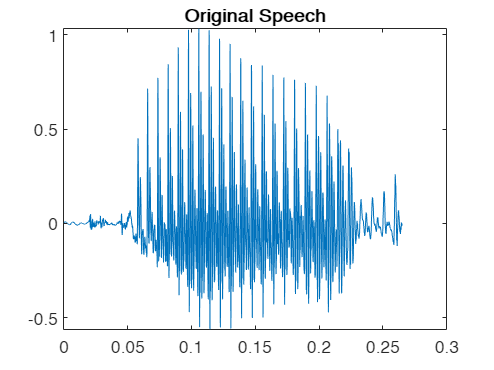

file = load('./Data_assignment_4/ex7M1.mat');
speech = file.speech2_10k;
Fs = 10000;
range = (1:length(speech))/Fs;
plot(range, speech);
title('Original Speech')

window = triang(0.03*Fs);
window = window';
shift = 0.015*Fs;

w_speech = zeros(1, length(window)*ceil(length(speech)/length(window)));
w_speech(1:length(speech)) = speech;
speech = w_speech;

num_shifts = ceil((length(speech) - length(window))/shift);
length(window) + num_shifts*shift;

num_windows = num_shifts+1;
windowed_speech = zeros(num_windows, length(window));
for i=0:num_windows-1
%     disp(i*shift+1)
%     disp((i+1)*length(window))
%     disp(length(window))
    windowed_speech(i+1, :) = speech(i*shift+1:(i*shift)+length(window)).*window;
end

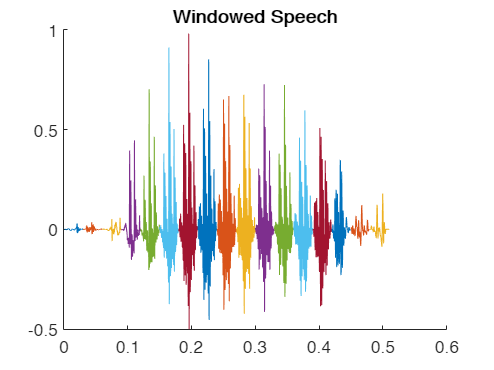

range_win = (1:length(window))/Fs;
figure;
hold on;
for i=1:num_windows
    plot(range_win+(i-1)*0.03, windowed_speech(i, :));
%     title('Window ', i);
end
title('Windowed Speech')
hold off;

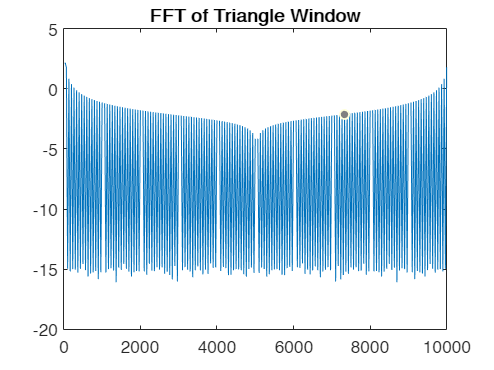

W = fft(window);
f_range = Fs*(1:length(window))/length(window);
plot(f_range, log10(abs(W)));
title('FFT of Triangle Window')

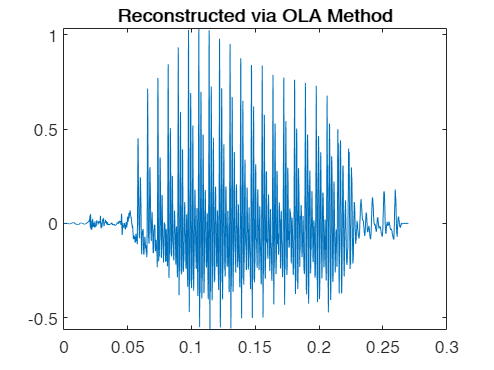

% Now reconstructing the original signal from the windowed signals
% Assuming 2700 samples again,
c_speech = zeros(1, length(speech));
for i=0:num_windows-1
    c_speech(i*shift+1:(i*shift)+length(window)) = c_speech(i*shift+1:(i*shift)+length(window)) + windowed_speech(i+1, :) * shift/W(1);
end
plot((1:length(speech))/Fs, c_speech);
title('Reconstructed via OLA Method')

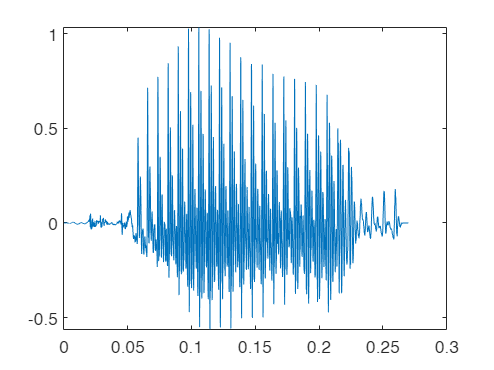

% Now reconstruction through LSE method
c_lse_speech = zeros(1, length(speech));
for i=0:num_windows-1
    c_lse_speech(i*shift+1:(i*shift)+length(window)) = c_lse_speech(i*shift+1:(i*shift)+length(window)) + windowed_speech(i+1, :) / W(1);
end
plot((1:length(speech))/Fs, c_speech);

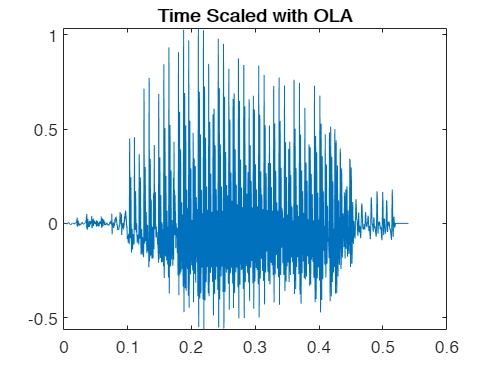

% Time expanding via OLA Method
n = 2;
c_double_speech = zeros(1, length(speech)*n);
for i=0:num_windows-1
    for j=0:1
    c_double_speech(((2*i+j)*shift+1) : (((2*i+j)*shift)+length(window))) = c_double_speech(((2*i+j)*shift+1) : (((2*i+j)*shift)+length(window))) + windowed_speech(i+1, :)*shift/W(1);
    end
end
plot((1:length(speech)*n)/Fs, c_double_speech);
title('Time Scaled with OLA');